fs=25e6;
bandwidth=9e6;
[b,a]=butter(20,bandwidth/(fs/2),'low');
[h,w]=freqz(b,a,'half',2048,fs);
%plot the frequency response of LPF
figure
plot(w/1e6,abs(h))
xlabel('Frequency (MHz)')
ylabel('Amplitude')
title('Frequency response of LPF')

filename='Frequency response of LPF.png'

filename = 'Frequency response of LPF.png'

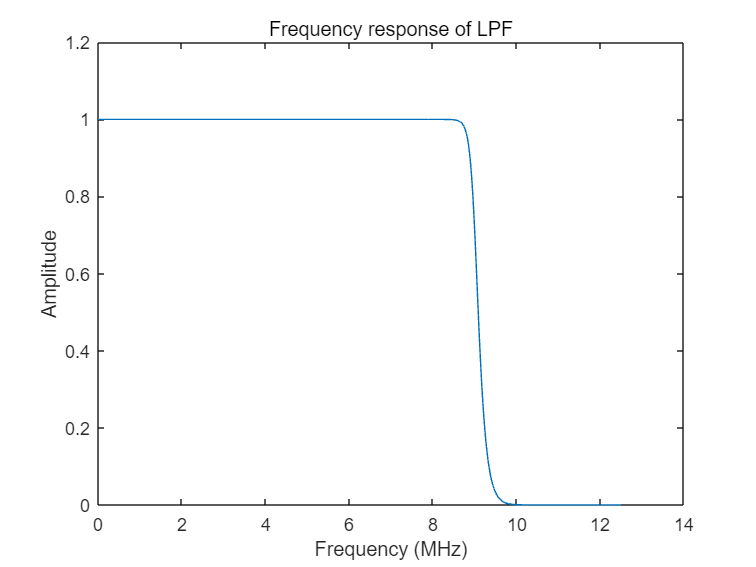

saveas(gcf, filename);